fs = 44100;                     % sample rate
f0 = 440;                       % fundamental frequency
k = 1/fs;                       % step size something

% Marimba params
L = 0.473;                      % length
rho = 7850;                     % material density (rosewood): 7850 or 800
E = 2.45387e+13;                % Young's modulus
I = 4.91e-14;                   % moment of inertia
A = 7.85e-07;                   % cross-sectional area

sigma0 = 0.2;                     % first damping term: 0.2 or 5
sigma1 = 0.0697;                    % second damping term: 0.0697 or 25

kappa = sqrt((E*I)/(rho*A))

kappa = 13.9829


c = 2 * L * f0                  % wave speed

c = 416.2400

h = sqrt(2 * kappa * k)         % h is something related to step size as well

h = 0.0252

N = floor(L/h)                  % the actual time step that we use 

N = 18


h = L/N                         % recalc of h

h = 0.0263

l = c * k/h                     % lambda

l = 0.3592


uNext = zeros(N+1, 1);
u = zeros(N+1, 1);
uPrev = zeros(N+1, 1);

u(3:9) = hann(7);
uPrev = u;

seconds = 1;
lengthSound = fs * seconds;

out = zeros(lengthSound, 1);
outIx = round((N+1)/3);

uLeft_1 = 2 * u(3) - u(4);                      % left boundary 1: u^n_{-1}=2u^n_{0}-u^n_1
uLeft_2 = u(5) - 2 * u(4) + 2 * uLeft_1;        % left boundary 2: u^n_{-2}=u^n_{2}-2u^n_{1}+2u^n_{-1}
uRight_1 = 2 * u(N-1) - u(N-2);                 % right boundary 1: u^n_{N+1}=2u^n_{N}-u^n_{N-1}
uRight_2 = u(N-3) - 2 * u(N-2) + 2 * uRight_1;  % right boundary 2: u^n_{N+2}=u^n_{N-2}-2u^n_{N-1}+2u^n_{N+1}

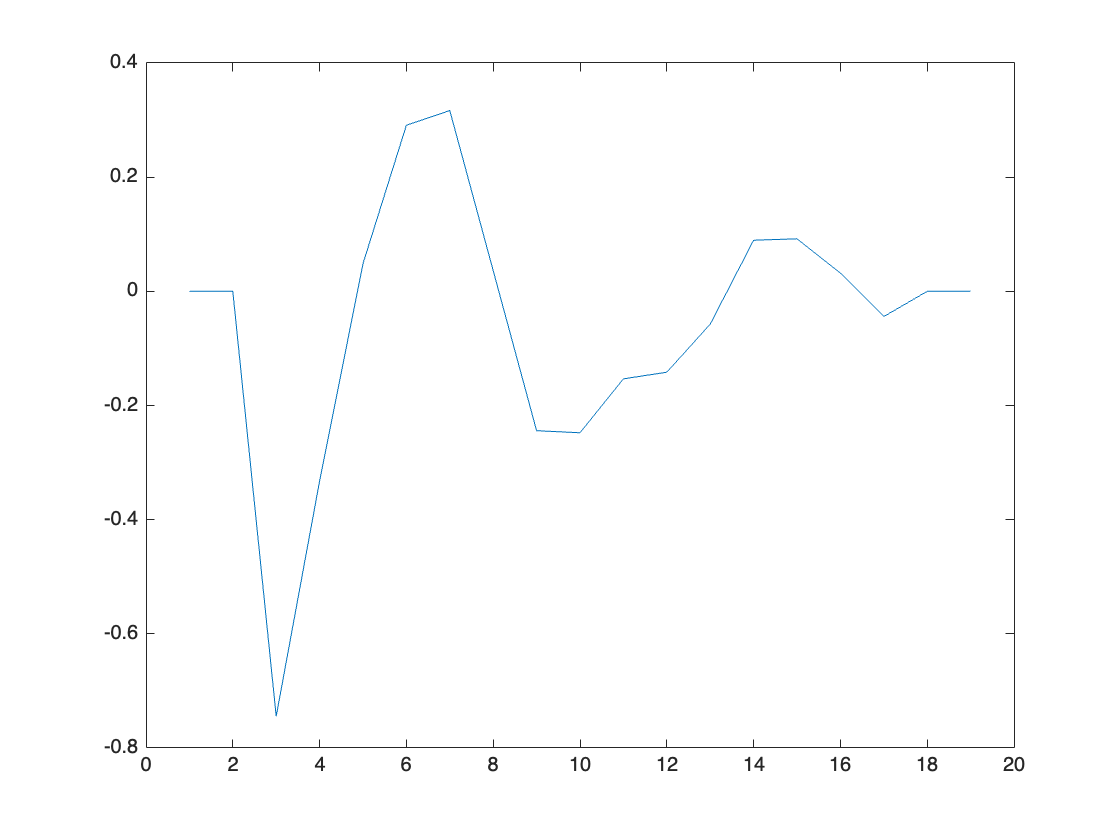


% Time integration loop
for j = 1:lengthSound
    % Compute displacement at interior points (excluding virtual boundary points)
    for l = 3:N-1
        uLeft_1 = 2 * u(3) - u(4);                      % left boundary  - 1 : u^n_{-1}=2u^n_{0}-u^n_1
        uLeft_2 = u(5) - 2 * u(4) + 2 * uLeft_1;        % left boundary  - 2 : u^n_{-2}=u^n_{2}-2u^n_{1}+2u^n_{-1}
        
        uRight_1 = 2 * u(N-1) - u(N-2);                 % right boundary + 1 : u^n_{N+1}=2u^n_{N}-u^n_{N-1}
        uRight_2 = u(N-3) - 2 * u(N-2) + 2 * uRight_1;  % right boundary + 2 : u^n_{N+2}=u^n_{N-2}-2u^n_{N-1}+2u^n_{N+1}
        
        uPrevRight = 2 * uPrev(N-1) - uPrev(N-2);       % right boundary + 1
        uPrevLeft = 2 * uPrev(3) - uPrev(4);            % left boundary  - 1

        if l == 3
            uNext(l) = (2 * u(l) - uPrev(l)) / (1 + 2 * sigma0 * (k / (rho * A))) + (k^2 / (rho * A)) * (- (E * I/h^4) * (u(l+2) - 4*u(l+1) + 6*u(l) - 4*uLeft_1 + uLeft_2) + (2 * sigma1 / k * h^2) * (u(l+1) - 2 * u(l) + uLeft_1 - uPrev(l + 1) + 2 * uPrev(l) - uPrevLeft));
        elseif l == 4
            uNext(l) = (2 * u(l) - uPrev(l)) / (1 + 2 * sigma0 * (k / (rho * A))) + (k^2 / (rho * A)) * (- (E * I/h^4) * (u(l+2) - 4*u(l+1) + 6*u(l) - 4*u(l-1) + uLeft_1) + (2 * sigma1 / k * h^2) * (u(l+1) - 2 * u(l) + u(l-1) - uPrev(l + 1) + 2 * uPrev(l) - uPrev(l - 1)));
        elseif l == N-1
            uNext(l) = (2 * u(l) - uPrev(l)) / (1 + 2 * sigma0 * (k / (rho * A))) + (k^2 / (rho * A)) * (- (E * I/h^4) * (uRight_2 - 4*uRight_1 + 6*u(l) - 4*u(l-1) + u(l-2)) + (2 * sigma1 / k * h^2) * (uRight_1 - 2 * u(l) + u(l-1) - uPrevRight + 2 * uPrev(l) - uPrev(l - 1)));
        elseif l == N-2
            uNext(l) = (2 * u(l) - uPrev(l)) / (1 + 2 * sigma0 * (k / (rho * A))) + (k^2 / (rho * A)) * (- (E * I/h^4) * (uRight_1 - 4*u(l+1) + 6*u(l) - 4*u(l-1) + u(l-2)) + (2 * sigma1 / k * h^2) * (u(l+1) - 2 * u(l) + u(l-1) - uPrev(l + 1) + 2 * uPrev(l) - uPrev(l - 1)));
        else
            uNext(l) = (2 * u(l) - uPrev(l)) / (1 + 2 * sigma0 * (k / (rho * A))) + (k^2 / (rho * A)) * (- (E * I/h^4) * (u(l+2) - 4*u(l+1) + 6*u(l) - 4*u(l-1) + u(l-2)) + (2 * sigma1 / k * h^2) * (u(l+1) - 2 * u(l) + u(l-1) - uPrev(l + 1) + 2 * uPrev(l) - uPrev(l - 1)));
        end

        % Compute uNext using the provided update equation
        %uNext(l) = (2 * u(l) - uPrev(l)) / (1 + 2 * sigma0 * (k / (rho * A))) + (k^2 / (rho * A)) * (- (E * I/h^4) * (u(l+2) - 4*u(l+1) + 6*u(l) - 4*u(l-1) + u(l-2)) + (2 * sigma1 / k * h^2) * (u(l+1) - 2 * u(l) + u(l-1) - uPrev(l + 1) + 2 * uPrev(l) - uPrev(l - 1)));
        %uNext(l) = (2 * u(l) - uPrev(l)) / (1 + 2 * sigma0 * (k / (rho * A))) + (k^2 / (rho * A)) * (- (E * I/h^4) * (next2 - 4 * next1 + 6*u(l) - 4 * prev1 + prev2) + (2 * sigma1 / k * h^2) * (next1 - 2 * u(l) + prev1 - uPrev(l + 1) + 2 * uPrev(l) - uPrev(l - 1)));
        %uNext(l) = (2 * u(l) - uPrev(l)) / (1 + 2 * sigma0 * (k / (rho * A))) + (k^2 / (rho * A)) * (- (E * I/h^4) * (next2 - 4 * next1 + 6*u(l) - 4 * prev1 + prev2) + (2 * sigma1 / k * h^2) * (next1 - 2 * u(l) + prev1 - uPrev(l + 1) + 2 * uPrev(l) - uPrevR));
    end
    
    % Store the output (from the physical domain)
    out(j) = uNext(outIx);
    
    % Update uPrev and u for next time step
    uPrev = u;
    u = uNext;
    
end


plot(uNext);
plot(out);
%out




soundsc(out, fs);

% uNext(i) = (2 * u(i) - uPrev(i) - ((kappa^2 * k^2) / h^4) * (u(i+2) - 4 * u(i+1) + 6 * u(i) - 4 * u(i-1) + u(i-2)) + sigma0 * k * uPrev(i)) / (1 + sigma1 * k); 

